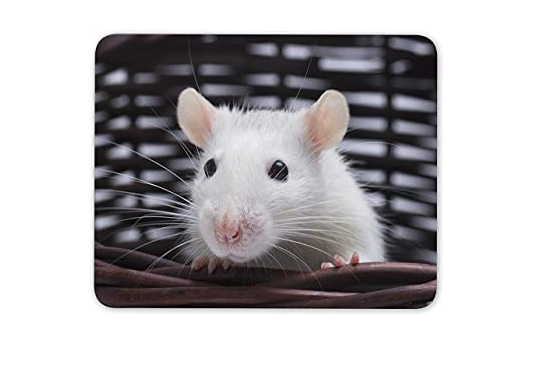

clc; clear; close all

img=imread('Test_rat_image.jpg');
imshow(img)

I=rgb2gray(img);


[I_test, threshold]=edge(I,'Canny');

Threshold (adjust slider that isolates the eyes the most)

threshold

threshold =     0.0688    0.1719


I_edge=edge(I,'Canny',3.9* threshold);

Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0]);
I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear);

Final images

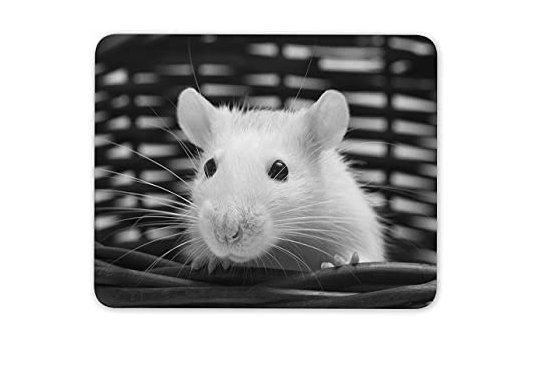

imshow(I)

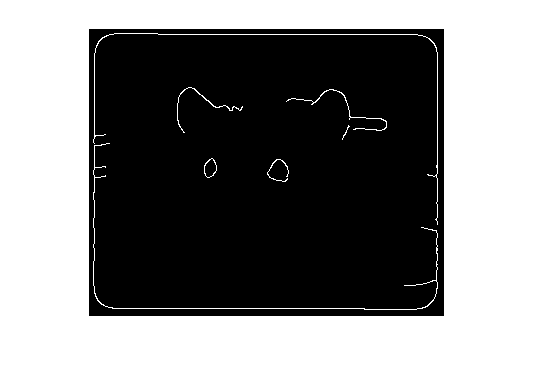

imshow(I_edge)

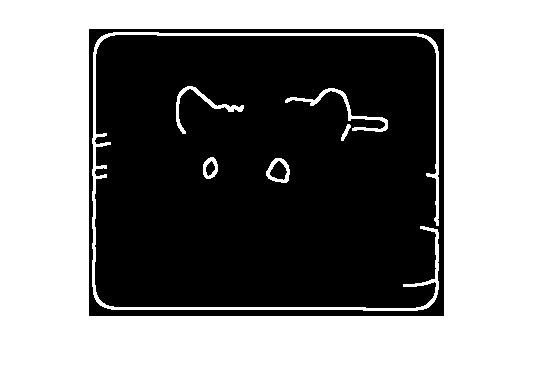


imshow(I_dilate)

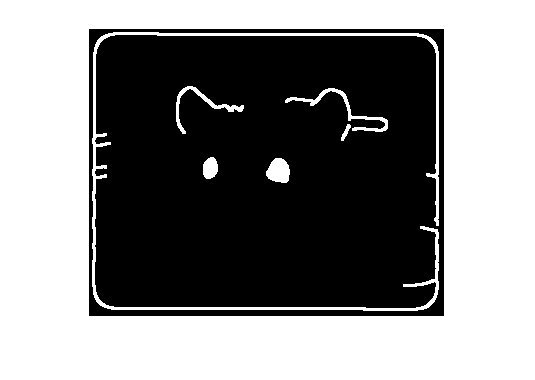

imshow(I_fill)

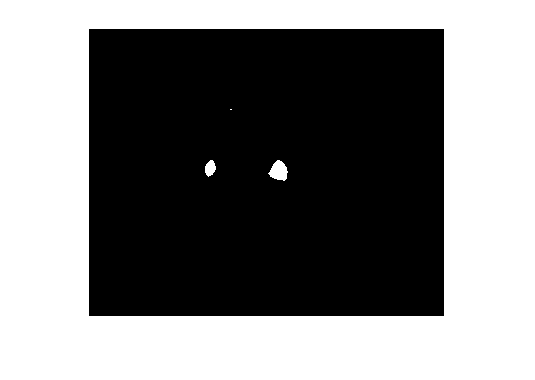

imshow(I_erode)

imshow(I_clear)

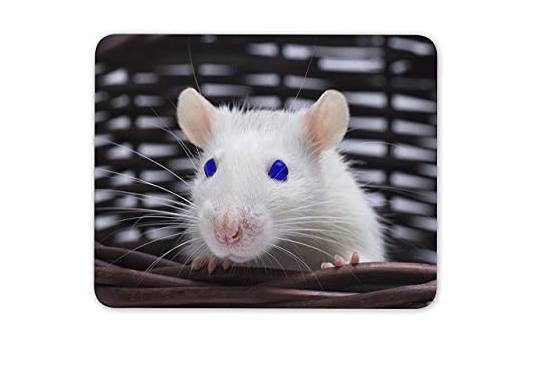


imshow(I_final)

Calculation of eye's area (biggest on image) 

region=regionprops(I_clear)

region = 3×1 struct array with fields:
    Area
    Centroid
    BoundingBox


Area=[region.Area]

Area =    132     2   276


eye_target=find(Area==max(Area))

eye_target = 3


% field that contains biggest area
eye_data=region(eye_target)

eye_data = struct with fields:
           Area: 276
       Centroid: [190.4420 142.6630]
    BoundingBox: [179.5000 131.5000 20 21]



% we want to evaluate the image of the best eye
bigeye_Area=Area(eye_target) 

bigeye_Area = 276


BoundingBox=eye_data.BoundingBox

BoundingBox =   179.5000  131.5000   20.0000   21.0000



X_dimension=BoundingBox(3)

X_dimension = 20

Y_dimension=BoundingBox(4)

Y_dimension = 21


XY_ratio= Y_dimension/X_dimension

XY_ratio = 1.0500

% Idea: rats in pain will have squintier eyes; therefore the x dimension
% will be larger and the y_dimension will be smaller resulting in a ratio
% closer to zero. Rats not in pain will have a ratio closer or greater to
% 1

%boundingbox=[] 


